% Set up
clc;
close all;
clear;

## **Load data**

## Re-organize data (eeg)

The data is set to m*n matrix

m = number of epochs

n = Frequency of Sampling * epoch length

% Initialize variables to store overall results
all_test_predictions = {};
all_test_labels = {};
all_test_indices = [];
overall_accuracies = zeros(1, 10);
per_subject_results = cell(1, 10);

% Main leave-one-out loop
for test = 1:10
    fprintf('\n=== Processing patient %d as test subject ===\n', test);
    
    EEG1 = [];
    EEG2 = [];
    STAGE = [];
    
    % load test data
    edfFilename = sprintf('R%d_edf.mat', test);
    xmlFilename = sprintf('R%d_xml.mat', test);
    load(edfFilename);
    load(xmlFilename);
    
    % We can know from the hdr that the 3rd and the 8th 
    % channel of the record is EEG signal
    Fs = hdr.samples(3);
    % every epoch lasts for epochLength seconds (30 seconds)
    numberOfEpochs = length(record(3,:)')/(Fs*epochLength)-1;   % cut the last epoch
    % Initialization of eeg1 and eeg2
    eeg1 = zeros(numberOfEpochs,Fs*epochLength);
    eeg2 = zeros(numberOfEpochs,Fs*epochLength);
    epochAmount = 1;    % How much epoches to cut for one row
    for i = 1:numberOfEpochs
        epochNumber = i;    % start epoch No.
        epochStart = epochNumber*Fs*epochLength;    % will cut the first epoch
        epochEnd = epochStart + epochAmount*Fs*epochLength - 1; % not include the end index
        t = linspace(0,epochAmount*30,epochAmount*Fs*epochLength);
        eeg1(i,:) = record(8,epochStart:epochEnd);
        eeg2(i,:) = record(3,epochStart:epochEnd);
    end
    EEG1_test = eeg1;
    EEG2_test = eeg2;
    % process the stages
    stages_epoch = zeros(1,numberOfEpochs);
    for i = 1:numberOfEpochs
        stages_epoch(i) = stages(i*30);
    end
    STAGE_test = stages_epoch;

    train = 1:10;
    train(train == test) = [];
    % load train data
    for n = train
        edfFilename = sprintf('R%d_edf.mat', n);
        xmlFilename = sprintf('R%d_xml.mat', n);
        load(edfFilename);
        load(xmlFilename);

        % every epoch lasts for epochLength seconds (30 seconds)
        numberOfEpochs = length(record(3,:)')/(Fs*epochLength)-1;   % cut the last epoch
        % Initialization of eeg1 and eeg2
        eeg1 = zeros(numberOfEpochs,Fs*epochLength);
        eeg2 = zeros(numberOfEpochs,Fs*epochLength);
        epochAmount = 1;    % How much epoches to cut for one row
        for i = 1:numberOfEpochs
            epochNumber = i;    % start epoch No.
            epochStart = epochNumber*Fs*epochLength;    % will cut the first epoch
            epochEnd = epochStart + epochAmount*Fs*epochLength - 1; % not include the end index
            t = linspace(0,epochAmount*30,epochAmount*Fs*epochLength);
            eeg1(i,:) = record(8,epochStart:epochEnd);
            eeg2(i,:) = record(3,epochStart:epochEnd);
        end
        EEG1 = [EEG1;eeg1];
        EEG2 = [EEG2;eeg2];
        % process the stages
        stages_epoch = zeros(1,numberOfEpochs);
        for i = 1:numberOfEpochs
            stages_epoch(i) = stages(i*30);
        end
        STAGE = [STAGE,stages_epoch];
    end


##     Plot for check

    % Plot the first epoch
    figure(1)
    subplot(2,1,1)
    plot(t,EEG1(1,:))
    subplot(2,1,2)
    plot(t,EEG2(1,:))

   

##  Remove the baseline drift

    % It will filter every row
    EEG1_filtered = baseline_drift_removal(EEG1,Fs,0.5);
    EEG2_filtered = baseline_drift_removal(EEG2,Fs,0.5);

    EEG1_test_filtered = baseline_drift_removal(EEG1_test,Fs,0.5);
    EEG2_test_filtered = baseline_drift_removal(EEG2_test,Fs,0.5);
    

##     Muscle noise filtering & Power line interference removal

    EEG1_filtered = muscle_noise_filtering(EEG1_filtered,Fs,30);
    EEG2_filtered = muscle_noise_filtering(EEG2_filtered,Fs,30);

    EEG1_test_filtered = muscle_noise_filtering(EEG1_test_filtered,Fs,30);
    EEG2_test_filtered = muscle_noise_filtering(EEG2_test_filtered,Fs,30);
    

##     Feature Extraction - Time-domain

features_time_eeg1 = extract_time_features(EEG1_filtered);
features_time_eeg2 = extract_time_features(EEG2_filtered);

features_time_eeg1_test = extract_time_features(EEG1_test_filtered);
features_time_eeg2_test = extract_time_features(EEG2_test_filtered);

feature_labels = {'Mean', 'Variance', 'Skewness', 'Kurtosis', ...
                  'Zero-Crossing Rate', 'Hjorth Activity', ...
                  'Hjorth Mobility', 'Hjorth Complexity'};

disp('Characteristics of EEG1 (Time-Domain):');
for i = 1:length(feature_labels)
    fprintf('%s: %.4f\n', feature_labels{i}, features_time_eeg1(i));
end

disp('Characteristics of EEG2 (Time-Domain):');
for i = 1:length(feature_labels)
    fprintf('%s: %.4f\n', feature_labels{i}, features_time_eeg2(i));
end

##     Feature Extraction - Frequency Domain

[features_freq_eeg1, Pxx_eeg1, freqs_eeg1] = extract_freq_features(EEG1_filtered, Fs);
[features_freq_eeg2, Pxx_eeg2, freqs_eeg2] = extract_freq_features(EEG2_filtered, Fs);

[features_freq_eeg1_test, Pxx_eeg1_test, freqs_eeg1_test] = extract_freq_features(EEG1_test_filtered, Fs);
[features_freq_eeg2_test, Pxx_eeg2_test, freqs_eeg2_test] = extract_freq_features(EEG2_test_filtered, Fs);

feature_labels_freq = {'Power Delta', 'Power Theta', 'Power Alpha', 'Power Beta', 'Power Gamma', ...
                      'Spectral Edge Frequency', ...
                      'Relative Delta', 'Relative Theta', 'Relative Alpha', 'Relative Beta', 'Relative Gamma'};

disp('Characteristics of EEG1 (Frequency-Domain):');
for i = 1:length(feature_labels_freq)
    fprintf('%s: %.4f\n', feature_labels_freq{i}, features_freq_eeg1(i));
end

disp('Characteristics of EEG2 (Frequency-Domain):');
for i = 1:length(feature_labels_freq)
    fprintf('%s: %.4f\n', feature_labels_freq{i}, features_freq_eeg2(i));
end

figure;
subplot(2,1,1);
plot(freqs_eeg1, Pxx_eeg1(1,:));
xlabel('Frequency (Hz)');
ylabel('Power');
title('EEG1 Power Spectrum');
xlim([0 40]);

subplot(2,1,2);
plot(freqs_eeg2, Pxx_eeg2(1,:));
xlabel('Frequency (Hz)');
ylabel('Power');
title('EEG2 Power Spectrum');
xlim([0 40]);



## Time Frequency

% Extract time-frequency features
features_timefreq_eeg1 = extract_timefreq_features(EEG1_filtered, Fs);
features_timefreq_eeg2 = extract_timefreq_features(EEG2_filtered, Fs);

features_timefreq_eeg1_test = extract_timefreq_features(EEG1_test_filtered, Fs);
features_timefreq_eeg2_test = extract_timefreq_features(EEG2_test_filtered, Fs);

% Append the new features to the existing feature set
features = [features_time_eeg1, features_freq_eeg1, features_timefreq_eeg1];
features_test = [features_time_eeg1_test, features_freq_eeg1_test, features_timefreq_eeg1_test];

% Display extracted features
disp('Time-Frequency Features for EEG1 (Wavelet Energy & Spectral Entropy):');
disp(features_timefreq_eeg1);  

disp('Time-Frequency Features for EEG2 (Wavelet Energy & Spectral Entropy):');
disp(features_timefreq_eeg2);  

disp('Time-Frequency Features for EEG1 (Test Data):');
disp(features_timefreq_eeg1_test);  

disp('Time-Frequency Features for EEG2 (Test Data):');
disp(features_timefreq_eeg2_test);  

% Plot extracted features for EEG1
figure;

subplot(2,1,1);
plot(features_timefreq_eeg1(:,1), 'b', 'LineWidth', 1.5); 
title('Wavelet Energy - EEG1');
ylabel('Energy');
xlabel('Epoch');
grid on;

subplot(2,1,2);
plot(features_timefreq_eeg1(:,2), 'r', 'LineWidth', 1.5); 
title('Spectral Entropy - EEG1');
ylabel('Entropy');
xlabel('Epoch');
grid on;

set(gcf, 'color', 'w'); % Set background color to white

% Plot extracted features for EEG2
figure;

subplot(2,1,1);
plot(features_timefreq_eeg2(:,1), 'b', 'LineWidth', 1.5); 
title('Wavelet Energy - EEG2');
ylabel('Energy');
xlabel('Epoch');
grid on;

subplot(2,1,2);
plot(features_timefreq_eeg2(:,2), 'r', 'LineWidth', 1.5); 
title('Spectral Entropy - EEG2');
ylabel('Entropy');
xlabel('Epoch');
grid on;

set(gcf, 'color', 'w'); % Set background color to white

##  Classification


=== Processing patient 1 as test subject ===


Characteristics of EEG1 (Time-Domain):


Mean: 0.0210
Variance: 0.1810
Skewness: -0.2066
Kurtosis: 0.0449
Zero-Crossing Rate: -0.0313
Hjorth Activity: -0.0355
Hjorth Mobility: 0.0293
Hjorth Complexity: -0.1628


Characteristics of EEG2 (Time-Domain):


Mean: 0.0262
Variance: 0.0159
Skewness: -0.0881
Kurtosis: -0.0394
Zero-Crossing Rate: -0.2019
Hjorth Activity: -0.0408
Hjorth Mobility: 0.0099
Hjorth Complexity: -0.1252


Characteristics of EEG1 (Frequency-Domain):


Power Delta: 6777.4693
Power Theta: 11229.3600
Power Alpha: 6513.6253
Power Beta: 9211.2052
Power Gamma: 11123.9064
Spectral Edge Frequency: 9768.1778
Relative Delta: 11233.6962
Relative Theta: 5817.6840
Relative Alpha: 9474.2615
Relative Beta: 3117.6757
Relative Gamma: 5575.2584


Characteristics of EEG2 (Frequency-Domain):


Power Delta: 6800.7709
Power Theta: 11995.7519
Power Alpha: 9237.0458
Power Beta: 9757.0650
Power Gamma: 10851.7076
Spectral Edge Frequency: 6514.8886
Relative Delta: 13328.4631
Relative Theta: 4860.2425
Relative Alpha: 10289.2710
Relative Beta: 4212.5765
Relative Gamma: 4973.0364


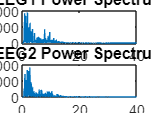

Time-Frequency Features for EEG1 (Wavelet Energy & Spectral Entropy):


   1.0e+05 *

  Column 1

    0.0155
    0.0155
    0.0149
    0.0144
    0.0136
    0.0195
    0.0290
    0.0273
    0.1121
    0.0164
    0.0169
    0.0181
    0.0184
    0.0161
    0.0155
    0.0148
    0.0147
    0.0150
    0.0144
    0.0127
    0.0138
    0.0132
    0.0138
    0.0193
    0.0166
    0.0127
    0.0148
    0.0144
    0.0146
    0.0131
    0.0135
    0.0128
    0.0124
    0.0129
    0.0123
    0.0114
    0.0905
    0.0139
    0.0142
    0.0134
    0.0130
    0.0116
    0.0126
    0.0125
    0.0177
    0.0116
    0.0120
    0.0131
    0.0114
    0.0104
    0.0117
    0.0112
    0.0118
    0.0116
    0.0121
    0.0218
    0.0122
    0.0187
    0.0118
    0.0114
    0.0114
    0.0134
    0.0116
    0.0111
    0.0120
    0.0112
    0.0127
    0.0131
    0.0136
    0.0206
    0.0154
    0.0165
    0.0153
    0.0145
    0.0194
    0.0146
    0.0133
    0.0188
    0.0149
    0.0162
    0.0137
    0.0140
    0.0161
    0.0134
    0.0156
    0.0216
    0.0173
    0.0149
    0.

Time-Frequency Features for EEG2 (Wavelet Energy & Spectral Entropy):


   1.0e+05 *

  Column 1

    0.0134
    0.0166
    0.0130
    0.0138
    0.0135
    0.0185
    0.0193
    0.0169
    0.0311
    0.0159
    0.0177
    0.0159
    0.0166
    0.0151
    0.0135
    0.0138
    0.0128
    0.0139
    0.0140
    0.0123
    0.0121
    0.0114
    0.0122
    0.0125
    0.0125
    0.0110
    0.0135
    0.0139
    0.0127
    0.0128
    0.0113
    0.0119
    0.0122
    0.0116
    0.0108
    0.0103
    0.0252
    0.0120
    0.0122
    0.0100
    0.0107
    0.0100
    0.0101
    0.0101
    0.0125
    0.0105
    0.0095
    0.0105
    0.0091
    0.0087
    0.0086
    0.0087
    0.0090
    0.0097
    0.0099
    0.0130
    0.0097
    0.0106
    0.0111
    0.0103
    0.0092
    0.0111
    0.0100
    0.0093
    0.0087
    0.0099
    0.0112
    0.0104
    0.0109
    0.0168
    0.0136
    0.0143
    0.0124
    0.0445
    0.0146
    0.0130
    0.0120
    0.0160
    0.0127
    0.0128
    0.0113
    0.0125
    0.0128
    0.0125
    0.0116
    0.0170
    0.0141
    0.0126
    0.

Time-Frequency Features for EEG1 (Test Data):


   1.0e+05 *

  Column 1

    1.2194
    0.6570
    0.7742
    0.5130
    0.7378
    0.5322
    0.7514
    0.6334
    0.4784
    0.5863
    0.5059
    0.5863
    1.0937
    0.5709
    0.8539
    0.8758
    0.8285
    1.0621
    0.8390
    1.0624
    1.1966
    0.6993
    0.8834
    1.2451
    0.3807
    0.4204
    0.7658
    0.0625
    0.0334
    0.0230
    0.0271
    0.4864
    0.1422
    0.0322
    0.0244
    0.0241
    0.0229
    0.0245
    0.0230
    0.0241
    0.0198
    0.0216
    0.0206
    0.0195
    0.0166
    0.0178
    0.0190
    0.0192
    0.0175
    0.0196
    0.1642
    0.2436
    0.0330
    0.0234
    0.0165
    0.0171
    0.0159
    0.0643
    0.0169
    0.0167
    0.0169
    0.1800
    0.1696
    0.0177
    0.0168
    0.0166
    0.0164
    0.0596
    0.1504
    0.0229
    0.0194
    0.0216
    0.0190
    0.0205
    0.0198
    0.0192
    0.0195
    0.0208
    0.0199
    0.0181
    0.0176
    0.0226
    0.0244
    0.0245
    0.0256
    0.0258
    0.1245
    0.0267
    0.

Time-Frequency Features for EEG2 (Test Data):


   1.0e+05 *

  Column 1

    0.2596
    0.2090
    0.5629
    0.2498
    0.8051
    0.4453
    0.3881
    0.2599
    0.1625
    0.3329
    0.2445
    0.2558
    0.6691
    0.3502
    0.2544
    0.1435
    0.2567
    0.1931
    0.1816
    0.3349
    0.3141
    0.1517
    0.2973
    0.3530
    0.2268
    0.1165
    0.1037
    0.0388
    0.0212
    0.0169
    0.0184
    0.2002
    0.0404
    0.0196
    0.0170
    0.0169
    0.0175
    0.0167
    0.0154
    0.0160
    0.0136
    0.0145
    0.0152
    0.0143
    0.0118
    0.0133
    0.0114
    0.0123
    0.0116
    0.0134
    0.0445
    0.1195
    0.0364
    0.0198
    0.0153
    0.0140
    0.0140
    0.0354
    0.0171
    0.0150
    0.0141
    0.0430
    0.0593
    0.0121
    0.0116
    0.0120
    0.0109
    0.0351
    0.0865
    0.0189
    0.0171
    0.0151
    0.0168
    0.0185
    0.0151
    0.0168
    0.0155
    0.0164
    0.0146
    0.0164
    0.0154
    0.0170
    0.0174
    0.0173
    0.0170
    0.0166
    0.0882
    0.0185
    0.

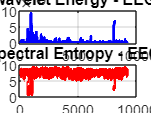

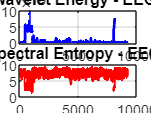

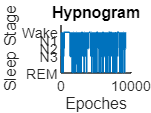

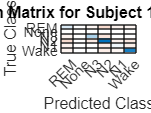


=== Processing patient 2 as test subject ===


Characteristics of EEG1 (Time-Domain):


Mean: 0.1629
Variance: 0.0198
Skewness: -0.0513
Kurtosis: 0.0056
Zero-Crossing Rate: 0.1305
Hjorth Activity: -0.1598
Hjorth Mobility: -0.1441
Hjorth Complexity: 0.0123


Characteristics of EEG2 (Time-Domain):


Mean: 0.0261
Variance: -0.2135
Skewness: -0.0569
Kurtosis: -0.0457
Zero-Crossing Rate: -0.0967
Hjorth Activity: 0.1239
Hjorth Mobility: 0.1421
Hjorth Complexity: -0.0234


Characteristics of EEG1 (Frequency-Domain):


Power Delta: 8342.0669
Power Theta: 3015.1777
Power Alpha: 16250.7399
Power Beta: 4874.3282
Power Gamma: 21155.5304
Spectral Edge Frequency: 6023.8947
Relative Delta: 9281.7551
Relative Theta: 4611.6760
Relative Alpha: 4697.1053
Relative Beta: 6782.4779
Relative Gamma: 5219.9735


Characteristics of EEG2 (Frequency-Domain):


Power Delta: 9327.1282
Power Theta: 2928.0047
Power Alpha: 8376.7920
Power Beta: 4231.3567
Power Gamma: 21630.7708
Spectral Edge Frequency: 3930.4638
Relative Delta: 6333.0173
Relative Theta: 3323.2778
Relative Alpha: 3551.0007
Relative Beta: 5196.6074
Relative Gamma: 2601.6914


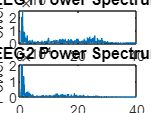

Time-Frequency Features for EEG1 (Wavelet Energy & Spectral Entropy):


   1.0e+05 *

  Column 1

    1.2194
    0.6570
    0.7742
    0.5130
    0.7378
    0.5322
    0.7514
    0.6334
    0.4784
    0.5863
    0.5059
    0.5863
    1.0937
    0.5709
    0.8539
    0.8758
    0.8285
    1.0621
    0.8390
    1.0624
    1.1966
    0.6993
    0.8834
    1.2451
    0.3807
    0.4204
    0.7658
    0.0625
    0.0334
    0.0230
    0.0271
    0.4864
    0.1422
    0.0322
    0.0244
    0.0241
    0.0229
    0.0245
    0.0230
    0.0241
    0.0198
    0.0216
    0.0206
    0.0195
    0.0166
    0.0178
    0.0190
    0.0192
    0.0175
    0.0196
    0.1642
    0.2436
    0.0330
    0.0234
    0.0165
    0.0171
    0.0159
    0.0643
    0.0169
    0.0167
    0.0169
    0.1800
    0.1696
    0.0177
    0.0168
    0.0166
    0.0164
    0.0596
    0.1504
    0.0229
    0.0194
    0.0216
    0.0190
    0.0205
    0.0198
    0.0192
    0.0195
    0.0208
    0.0199
    0.0181
    0.0176
    0.0226
    0.0244
    0.0245
    0.0256
    0.0258
    0.1245
    0.0267
    0.

Time-Frequency Features for EEG2 (Wavelet Energy & Spectral Entropy):


   1.0e+05 *

  Column 1

    0.2596
    0.2090
    0.5629
    0.2498
    0.8051
    0.4453
    0.3881
    0.2599
    0.1625
    0.3329
    0.2445
    0.2558
    0.6691
    0.3502
    0.2544
    0.1435
    0.2567
    0.1931
    0.1816
    0.3349
    0.3141
    0.1517
    0.2973
    0.3530
    0.2268
    0.1165
    0.1037
    0.0388
    0.0212
    0.0169
    0.0184
    0.2002
    0.0404
    0.0196
    0.0170
    0.0169
    0.0175
    0.0167
    0.0154
    0.0160
    0.0136
    0.0145
    0.0152
    0.0143
    0.0118
    0.0133
    0.0114
    0.0123
    0.0116
    0.0134
    0.0445
    0.1195
    0.0364
    0.0198
    0.0153
    0.0140
    0.0140
    0.0354
    0.0171
    0.0150
    0.0141
    0.0430
    0.0593
    0.0121
    0.0116
    0.0120
    0.0109
    0.0351
    0.0865
    0.0189
    0.0171
    0.0151
    0.0168
    0.0185
    0.0151
    0.0168
    0.0155
    0.0164
    0.0146
    0.0164
    0.0154
    0.0170
    0.0174
    0.0173
    0.0170
    0.0166
    0.0882
    0.0185
    0.

Time-Frequency Features for EEG1 (Test Data):


   1.0e+05 *

  Column 1

    0.0155
    0.0155
    0.0149
    0.0144
    0.0136
    0.0195
    0.0290
    0.0273
    0.1121
    0.0164
    0.0169
    0.0181
    0.0184
    0.0161
    0.0155
    0.0148
    0.0147
    0.0150
    0.0144
    0.0127
    0.0138
    0.0132
    0.0138
    0.0193
    0.0166
    0.0127
    0.0148
    0.0144
    0.0146
    0.0131
    0.0135
    0.0128
    0.0124
    0.0129
    0.0123
    0.0114
    0.0905
    0.0139
    0.0142
    0.0134
    0.0130
    0.0116
    0.0126
    0.0125
    0.0177
    0.0116
    0.0120
    0.0131
    0.0114
    0.0104
    0.0117
    0.0112
    0.0118
    0.0116
    0.0121
    0.0218
    0.0122
    0.0187
    0.0118
    0.0114
    0.0114
    0.0134
    0.0116
    0.0111
    0.0120
    0.0112
    0.0127
    0.0131
    0.0136
    0.0206
    0.0154
    0.0165
    0.0153
    0.0145
    0.0194
    0.0146
    0.0133
    0.0188
    0.0149
    0.0162
    0.0137
    0.0140
    0.0161
    0.0134
    0.0156
    0.0216
    0.0173
    0.0149
    0.

Time-Frequency Features for EEG2 (Test Data):


   1.0e+05 *

  Column 1

    0.0134
    0.0166
    0.0130
    0.0138
    0.0135
    0.0185
    0.0193
    0.0169
    0.0311
    0.0159
    0.0177
    0.0159
    0.0166
    0.0151
    0.0135
    0.0138
    0.0128
    0.0139
    0.0140
    0.0123
    0.0121
    0.0114
    0.0122
    0.0125
    0.0125
    0.0110
    0.0135
    0.0139
    0.0127
    0.0128
    0.0113
    0.0119
    0.0122
    0.0116
    0.0108
    0.0103
    0.0252
    0.0120
    0.0122
    0.0100
    0.0107
    0.0100
    0.0101
    0.0101
    0.0125
    0.0105
    0.0095
    0.0105
    0.0091
    0.0087
    0.0086
    0.0087
    0.0090
    0.0097
    0.0099
    0.0130
    0.0097
    0.0106
    0.0111
    0.0103
    0.0092
    0.0111
    0.0100
    0.0093
    0.0087
    0.0099
    0.0112
    0.0104
    0.0109
    0.0168
    0.0136
    0.0143
    0.0124
    0.0445
    0.0146
    0.0130
    0.0120
    0.0160
    0.0127
    0.0128
    0.0113
    0.0125
    0.0128
    0.0125
    0.0116
    0.0170
    0.0141
    0.0126
    0.

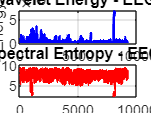

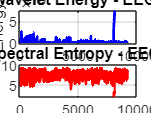

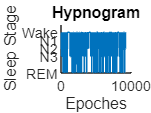

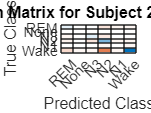


=== Processing patient 3 as test subject ===


Characteristics of EEG1 (Time-Domain):


Mean: 0.1629
Variance: 0.0198
Skewness: -0.0513
Kurtosis: 0.0056
Zero-Crossing Rate: 0.1305
Hjorth Activity: -0.1598
Hjorth Mobility: -0.1441
Hjorth Complexity: 0.0123


Characteristics of EEG2 (Time-Domain):


Mean: 0.0261
Variance: -0.2135
Skewness: -0.0569
Kurtosis: -0.0457
Zero-Crossing Rate: -0.0967
Hjorth Activity: 0.1239
Hjorth Mobility: 0.1421
Hjorth Complexity: -0.0234


Characteristics of EEG1 (Frequency-Domain):


Power Delta: 8342.0669
Power Theta: 3015.1777
Power Alpha: 16250.7399
Power Beta: 4874.3282
Power Gamma: 21155.5304
Spectral Edge Frequency: 6023.8947
Relative Delta: 9281.7551
Relative Theta: 4611.6760
Relative Alpha: 4697.1053
Relative Beta: 6782.4779
Relative Gamma: 5219.9735


Characteristics of EEG2 (Frequency-Domain):


Power Delta: 9327.1282
Power Theta: 2928.0047
Power Alpha: 8376.7920
Power Beta: 4231.3567
Power Gamma: 21630.7708
Spectral Edge Frequency: 3930.4638
Relative Delta: 6333.0173
Relative Theta: 3323.2778
Relative Alpha: 3551.0007
Relative Beta: 5196.6074
Relative Gamma: 2601.6914


Time-Frequency Features for EEG1 (Wavelet Energy & Spectral Entropy):


   1.0e+05 *

  Column 1

    1.2194
    0.6570
    0.7742
    0.5130
    0.7378
    0.5322
    0.7514
    0.6334
    0.4784
    0.5863
    0.5059
    0.5863
    1.0937
    0.5709
    0.8539
    0.8758
    0.8285
    1.0621
    0.8390
    1.0624
    1.1966
    0.6993
    0.8834
    1.2451
    0.3807
    0.4204
    0.7658
    0.0625
    0.0334
    0.0230
    0.0271
    0.4864
    0.1422
    0.0322
    0.0244
    0.0241
    0.0229
    0.0245
    0.0230
    0.0241
    0.0198
    0.0216
    0.0206
    0.0195
    0.0166
    0.0178
    0.0190
    0.0192
    0.0175
    0.0196
    0.1642
    0.2436
    0.0330
    0.0234
    0.0165
    0.0171
    0.0159
    0.0643
    0.0169
    0.0167
    0.0169
    0.1800
    0.1696
    0.0177
    0.0168
    0.0166
    0.0164
    0.0596
    0.1504
    0.0229
    0.0194
    0.0216
    0.0190
    0.0205
    0.0198
    0.0192
    0.0195
    0.0208
    0.0199
    0.0181
    0.0176
    0.0226
    0.0244
    0.0245
    0.0256
    0.0258
    0.1245
    0.0267
    0.

Time-Frequency Features for EEG2 (Wavelet Energy & Spectral Entropy):


   1.0e+05 *

  Column 1

    0.2596
    0.2090
    0.5629
    0.2498
    0.8051
    0.4453
    0.3881
    0.2599
    0.1625
    0.3329
    0.2445
    0.2558
    0.6691
    0.3502
    0.2544
    0.1435
    0.2567
    0.1931
    0.1816
    0.3349
    0.3141
    0.1517
    0.2973
    0.3530
    0.2268
    0.1165
    0.1037
    0.0388
    0.0212
    0.0169
    0.0184
    0.2002
    0.0404
    0.0196
    0.0170
    0.0169
    0.0175
    0.0167
    0.0154
    0.0160
    0.0136
    0.0145
    0.0152
    0.0143
    0.0118
    0.0133
    0.0114
    0.0123
    0.0116
    0.0134
    0.0445
    0.1195
    0.0364
    0.0198
    0.0153
    0.0140
    0.0140
    0.0354
    0.0171
    0.0150
    0.0141
    0.0430
    0.0593
    0.0121
    0.0116
    0.0120
    0.0109
    0.0351
    0.0865
    0.0189
    0.0171
    0.0151
    0.0168
    0.0185
    0.0151
    0.0168
    0.0155
    0.0164
    0.0146
    0.0164
    0.0154
    0.0170
    0.0174
    0.0173
    0.0170
    0.0166
    0.0882
    0.0185
    0.

Time-Frequency Features for EEG1 (Test Data):


   1.0e+05 *

  Column 1

    0.1154
    0.1885
    0.1769
    0.3640
    0.2606
    0.2059
    0.2212
    0.3865
    1.4254
    0.8788
    0.7361
    0.8859
    1.3040
    0.6158
    0.7597
    0.9449
    1.0728
    1.0639
    0.4323
    0.3994
    1.0649
    2.0857
    2.9858
    2.2114
    2.8378
    1.9265
    0.9956
    1.7689
    2.2907
    0.2249
    1.6158
    1.9842
    0.1330
    0.1408
    1.0674
    1.7848
    1.7544
    1.5005
    2.1988
    1.5057
    2.7905
    0.7160
    0.0749
    0.0667
    0.0730
    0.0901
    0.1100
    0.2337
    0.1506
    0.1718
    0.0927
    0.1273
    0.1160
    0.0881
    0.1266
    0.1133
    0.0959
    0.0826
    0.1410
    0.1245
    0.0813
    0.0866
    0.4410
    0.3738
    0.1134
    0.2255
    0.1266
    0.0646
    0.0895
    0.0845
    0.1455
    0.5799
    0.7312
    1.2601
    0.3978
    0.4657
    0.5654
    0.9895
    1.0683
    0.5010
    0.9287
    0.9542
    2.0653
    1.5503
    2.8128
    2.1327
    2.3549
    1.4822
    1.

Time-Frequency Features for EEG2 (Test Data):


   1.0e+05 *

  Column 1

    0.0568
    0.2098
    0.1984
    0.4619
    0.1475
    0.0620
    0.0587
    1.3653
    0.5739
    1.4291
    0.3259
    0.3682
    1.8423
    0.6699
    0.1225
    0.1042
    0.3334
    0.6487
    0.2483
    0.3220
    0.2894
    0.3362
    0.2594
    0.5100
    0.6444
    0.7806
    1.0259
    0.8458
    0.8137
    0.2194
    1.3044
    0.9753
    0.2866
    0.1352
    0.5517
    0.8609
    1.2695
    1.4756
    1.3227
    0.5281
    1.0709
    0.3345
    0.0906
    0.0676
    0.0787
    0.0849
    0.1050
    0.1103
    0.1059
    0.0814
    0.0801
    0.1112
    0.1003
    0.0998
    0.1143
    0.0824
    0.0857
    0.0645
    0.1071
    0.1202
    0.0725
    0.0623
    0.3525
    0.2800
    0.2875
    0.3632
    0.7848
    0.1118
    0.1304
    0.1654
    0.3058
    0.3294
    0.1877
    0.4234
    0.5558
    0.3025
    0.5519
    0.6049
    0.8206
    0.9036
    0.8244
    0.7004
    1.7432
    1.6035
    2.4246
    1.8134
    2.4223
    1.8527
    1.

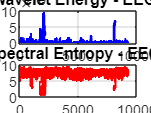

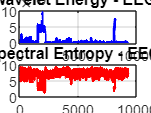

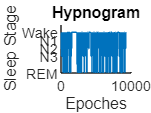

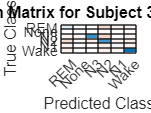


=== Processing patient 4 as test subject ===


Characteristics of EEG1 (Time-Domain):


Mean: 0.1629
Variance: 0.0198
Skewness: -0.0513
Kurtosis: 0.0056
Zero-Crossing Rate: 0.1305
Hjorth Activity: -0.1598
Hjorth Mobility: -0.1441
Hjorth Complexity: 0.0123


Characteristics of EEG2 (Time-Domain):


Mean: 0.0261
Variance: -0.2135
Skewness: -0.0569
Kurtosis: -0.0457
Zero-Crossing Rate: -0.0967
Hjorth Activity: 0.1239
Hjorth Mobility: 0.1421
Hjorth Complexity: -0.0234


Characteristics of EEG1 (Frequency-Domain):


Power Delta: 8342.0669
Power Theta: 3015.1777
Power Alpha: 16250.7399
Power Beta: 4874.3282
Power Gamma: 21155.5304
Spectral Edge Frequency: 6023.8947
Relative Delta: 9281.7551
Relative Theta: 4611.6760
Relative Alpha: 4697.1053
Relative Beta: 6782.4779
Relative Gamma: 5219.9735


Characteristics of EEG2 (Frequency-Domain):


Power Delta: 9327.1282
Power Theta: 2928.0047
Power Alpha: 8376.7920
Power Beta: 4231.3567
Power Gamma: 21630.7708
Spectral Edge Frequency: 3930.4638
Relative Delta: 6333.0173
Relative Theta: 3323.2778
Relative Alpha: 3551.0007
Relative Beta: 5196.6074
Relative Gamma: 2601.6914


Time-Frequency Features for EEG1 (Wavelet Energy & Spectral Entropy):


   1.0e+05 *

  Column 1

    1.2194
    0.6570
    0.7742
    0.5130
    0.7378
    0.5322
    0.7514
    0.6334
    0.4784
    0.5863
    0.5059
    0.5863
    1.0937
    0.5709
    0.8539
    0.8758
    0.8285
    1.0621
    0.8390
    1.0624
    1.1966
    0.6993
    0.8834
    1.2451
    0.3807
    0.4204
    0.7658
    0.0625
    0.0334
    0.0230
    0.0271
    0.4864
    0.1422
    0.0322
    0.0244
    0.0241
    0.0229
    0.0245
    0.0230
    0.0241
    0.0198
    0.0216
    0.0206
    0.0195
    0.0166
    0.0178
    0.0190
    0.0192
    0.0175
    0.0196
    0.1642
    0.2436
    0.0330
    0.0234
    0.0165
    0.0171
    0.0159
    0.0643
    0.0169
    0.0167
    0.0169
    0.1800
    0.1696
    0.0177
    0.0168
    0.0166
    0.0164
    0.0596
    0.1504
    0.0229
    0.0194
    0.0216
    0.0190
    0.0205
    0.0198
    0.0192
    0.0195
    0.0208
    0.0199
    0.0181
    0.0176
    0.0226
    0.0244
    0.0245
    0.0256
    0.0258
    0.1245
    0.0267
    0.

Time-Frequency Features for EEG2 (Wavelet Energy & Spectral Entropy):


   1.0e+05 *

  Column 1

    0.2596
    0.2090
    0.5629
    0.2498
    0.8051
    0.4453
    0.3881
    0.2599
    0.1625
    0.3329
    0.2445
    0.2558
    0.6691
    0.3502
    0.2544
    0.1435
    0.2567
    0.1931
    0.1816
    0.3349
    0.3141
    0.1517
    0.2973
    0.3530
    0.2268
    0.1165
    0.1037
    0.0388
    0.0212
    0.0169
    0.0184
    0.2002
    0.0404
    0.0196
    0.0170
    0.0169
    0.0175
    0.0167
    0.0154
    0.0160
    0.0136
    0.0145
    0.0152
    0.0143
    0.0118
    0.0133
    0.0114
    0.0123
    0.0116
    0.0134
    0.0445
    0.1195
    0.0364
    0.0198
    0.0153
    0.0140
    0.0140
    0.0354
    0.0171
    0.0150
    0.0141
    0.0430
    0.0593
    0.0121
    0.0116
    0.0120
    0.0109
    0.0351
    0.0865
    0.0189
    0.0171
    0.0151
    0.0168
    0.0185
    0.0151
    0.0168
    0.0155
    0.0164
    0.0146
    0.0164
    0.0154
    0.0170
    0.0174
    0.0173
    0.0170
    0.0166
    0.0882
    0.0185
    0.

Time-Frequency Features for EEG1 (Test Data):


   1.0e+04 *

  Column 1

    0.9352
    1.4605
    1.4192
    1.1726
    1.6662
    3.7247
    2.6888
    0.9693
    0.7178
    0.6745
    0.6044
    0.6420
    0.7670
    0.9851
    0.5211
    0.2902
    0.2839
    0.3010
    0.3091
    0.2552
    0.3101
    0.4657
    0.5405
    0.4946
    0.5064
    0.4658
    0.5775
    0.5008
    0.5336
    0.5179
    0.3184
    0.2828
    0.2679
    0.2498
    0.1842
    0.2481
    0.2234
    0.2683
    0.2514
    0.5036
    0.5076
    0.3698
    0.2224
    0.1984
    0.1785
    0.1856
    0.2613
    0.3855
    1.3381
    1.3728
    1.9142
    2.3064
    0.7253
    0.8435
    0.6377
    1.2040
    2.9031
    2.7934
    2.6304
    4.0304
    6.6282
    7.4095
    7.8153
    1.8563
    3.9579
    4.8617
    3.4231
    2.8845
    3.5047
    8.4786
    6.5457
    5.2906
    4.5269
    4.3961
    4.4391
    4.1050
    3.1726
    2.6858
    5.3686
    2.1164
    1.6624
    0.8896
    0.4922
    0.3175
    0.3065
    0.1872
    0.1246
    0.1347
    0.

Time-Frequency Features for EEG2 (Test Data):


   1.0e+04 *

  Column 1

    0.1937
    0.1831
    0.2324
    0.2517
    0.2629
    0.6232
    1.1702
    0.3846
    0.2952
    0.2186
    0.2268
    0.2668
    0.2587
    0.3935
    0.3504
    0.2958
    0.2646
    0.2424
    0.2187
    0.2223
    0.1962
    0.2096
    0.1841
    0.1947
    0.1954
    0.1653
    0.1775
    0.1864
    0.2544
    0.4383
    0.3981
    0.4350
    0.1415
    0.1649
    0.1394
    0.1462
    0.2616
    0.2706
    0.1570
    0.6536
    2.1870
    1.4356
    0.5526
    0.4579
    0.3730
    0.3330
    0.2177
    0.1693
    0.4055
    0.5176
    1.1815
    2.0697
    0.8704
    0.7175
    0.2825
    1.0649
    0.7612
    0.7037
    1.1827
    1.2685
    2.3461
    2.6945
    1.9575
    0.7917
    0.8192
    0.9266
    0.7583
    0.7447
    0.5441
    0.7360
    0.4167
    0.4138
    0.4516
    0.4208
    0.4922
    0.4274
    0.3919
    0.3948
    0.6216
    0.4719
    0.4996
    0.3076
    0.2545
    0.1834
    0.1904
    0.1498
    0.1648
    0.1802
    0.

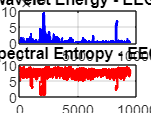

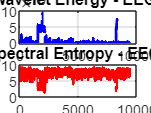

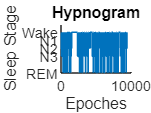

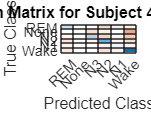


=== Processing patient 5 as test subject ===


Characteristics of EEG1 (Time-Domain):


Mean: 0.1629
Variance: 0.0198
Skewness: -0.0513
Kurtosis: 0.0056
Zero-Crossing Rate: 0.1305
Hjorth Activity: -0.1598
Hjorth Mobility: -0.1441
Hjorth Complexity: 0.0123


Characteristics of EEG2 (Time-Domain):


Mean: 0.0261
Variance: -0.2135
Skewness: -0.0569
Kurtosis: -0.0457
Zero-Crossing Rate: -0.0967
Hjorth Activity: 0.1239
Hjorth Mobility: 0.1421
Hjorth Complexity: -0.0234


Characteristics of EEG1 (Frequency-Domain):


Power Delta: 8342.0669
Power Theta: 3015.1777
Power Alpha: 16250.7399
Power Beta: 4874.3282
Power Gamma: 21155.5304
Spectral Edge Frequency: 6023.8947
Relative Delta: 9281.7551
Relative Theta: 4611.6760
Relative Alpha: 4697.1053
Relative Beta: 6782.4779
Relative Gamma: 5219.9735


Characteristics of EEG2 (Frequency-Domain):


Power Delta: 9327.1282
Power Theta: 2928.0047
Power Alpha: 8376.7920
Power Beta: 4231.3567
Power Gamma: 21630.7708
Spectral Edge Frequency: 3930.4638
Relative Delta: 6333.0173
Relative Theta: 3323.2778
Relative Alpha: 3551.0007
Relative Beta: 5196.6074
Relative Gamma: 2601.6914


Time-Frequency Features for EEG1 (Wavelet Energy & Spectral Entropy):


   1.0e+05 *

  Column 1

    1.2194
    0.6570
    0.7742
    0.5130
    0.7378
    0.5322
    0.7514
    0.6334
    0.4784
    0.5863
    0.5059
    0.5863
    1.0937
    0.5709
    0.8539
    0.8758
    0.8285
    1.0621
    0.8390
    1.0624
    1.1966
    0.6993
    0.8834
    1.2451
    0.3807
    0.4204
    0.7658
    0.0625
    0.0334
    0.0230
    0.0271
    0.4864
    0.1422
    0.0322
    0.0244
    0.0241
    0.0229
    0.0245
    0.0230
    0.0241
    0.0198
    0.0216
    0.0206
    0.0195
    0.0166
    0.0178
    0.0190
    0.0192
    0.0175
    0.0196
    0.1642
    0.2436
    0.0330
    0.0234
    0.0165
    0.0171
    0.0159
    0.0643
    0.0169
    0.0167
    0.0169
    0.1800
    0.1696
    0.0177
    0.0168
    0.0166
    0.0164
    0.0596
    0.1504
    0.0229
    0.0194
    0.0216
    0.0190
    0.0205
    0.0198
    0.0192
    0.0195
    0.0208
    0.0199
    0.0181
    0.0176
    0.0226
    0.0244
    0.0245
    0.0256
    0.0258
    0.1245
    0.0267
    0.

Time-Frequency Features for EEG2 (Wavelet Energy & Spectral Entropy):


   1.0e+05 *

  Column 1

    0.2596
    0.2090
    0.5629
    0.2498
    0.8051
    0.4453
    0.3881
    0.2599
    0.1625
    0.3329
    0.2445
    0.2558
    0.6691
    0.3502
    0.2544
    0.1435
    0.2567
    0.1931
    0.1816
    0.3349
    0.3141
    0.1517
    0.2973
    0.3530
    0.2268
    0.1165
    0.1037
    0.0388
    0.0212
    0.0169
    0.0184
    0.2002
    0.0404
    0.0196
    0.0170
    0.0169
    0.0175
    0.0167
    0.0154
    0.0160
    0.0136
    0.0145
    0.0152
    0.0143
    0.0118
    0.0133
    0.0114
    0.0123
    0.0116
    0.0134
    0.0445
    0.1195
    0.0364
    0.0198
    0.0153
    0.0140
    0.0140
    0.0354
    0.0171
    0.0150
    0.0141
    0.0430
    0.0593
    0.0121
    0.0116
    0.0120
    0.0109
    0.0351
    0.0865
    0.0189
    0.0171
    0.0151
    0.0168
    0.0185
    0.0151
    0.0168
    0.0155
    0.0164
    0.0146
    0.0164
    0.0154
    0.0170
    0.0174
    0.0173
    0.0170
    0.0166
    0.0882
    0.0185
    0.

Time-Frequency Features for EEG1 (Test Data):


   1.0e+05 *

  Column 1

    0.1217
    0.8179
    0.4518
    0.2728
    0.3732
    0.4586
    0.9577
    1.2277
    1.2382
    0.8668
    0.4725
    0.0771
    0.0607
    0.0461
    0.0625
    0.0611
    0.0436
    0.0701
    0.0571
    0.0353
    0.0330
    0.0274
    0.0256
    0.0223
    0.0225
    0.0216
    0.0216
    0.0203
    0.0228
    0.0264
    0.0229
    0.0206
    0.0217
    0.0223
    0.0223
    0.0180
    0.0202
    0.0193
    0.0174
    0.0188
    0.0179
    0.0175
    0.0169
    0.0159
    0.0140
    0.0158
    0.0152
    0.0165
    0.0168
    0.0154
    0.0149
    0.0145
    0.0151
    0.1190
    0.0450
    0.8788
    0.6693
    0.2221
    0.5095
    0.3570
    0.4343
    0.8847
    1.2925
    0.0922
    0.1431
    0.1077
    0.2235
    0.1709
    0.0939
    0.1256
    0.1116
    0.1702
    0.1647
    0.1905
    0.2049
    0.2400
    0.3013
    0.2681
    0.3566
    0.2956
    0.4226
    0.1098
    0.2570
    0.2504
    0.3233
    0.3412
    0.4019
    0.4467
    0.

Time-Frequency Features for EEG2 (Test Data):


   1.0e+05 *

  Column 1

    0.1240
    0.3200
    0.0788
    0.0594
    0.1073
    0.1886
    0.1780
    0.6658
    0.3284
    0.6469
    0.4259
    0.0822
    0.0703
    0.1102
    0.1223
    0.1375
    0.0604
    0.1097
    0.0565
    0.0236
    0.0213
    0.0179
    0.0180
    0.0139
    0.0138
    0.0151
    0.0145
    0.0129
    0.0133
    0.0180
    0.0130
    0.0128
    0.0130
    0.0128
    0.0125
    0.0123
    0.0121
    0.0112
    0.0103
    0.0112
    0.0097
    0.0102
    0.0096
    0.0102
    0.0090
    0.0084
    0.0102
    0.0093
    0.0098
    0.0083
    0.0092
    0.0085
    0.0086
    0.0393
    0.0323
    0.3999
    0.3519
    0.2664
    0.2277
    0.3124
    0.4020
    0.6074
    0.4202
    0.0562
    0.0545
    0.1077
    0.1207
    0.3333
    0.2883
    0.2389
    0.5105
    0.3117
    0.3069
    0.4316
    0.3049
    0.3009
    0.4051
    0.6207
    0.6002
    0.6038
    0.6344
    0.4297
    0.9401
    1.0138
    0.8245
    0.9187
    0.9523
    0.9840
    0.

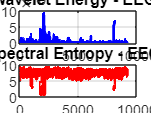

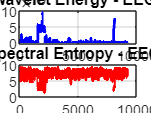

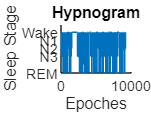

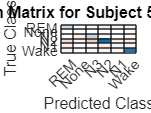


=== Processing patient 6 as test subject ===


Characteristics of EEG1 (Time-Domain):


Mean: 0.1629
Variance: 0.0198
Skewness: -0.0513
Kurtosis: 0.0056
Zero-Crossing Rate: 0.1305
Hjorth Activity: -0.1598
Hjorth Mobility: -0.1441
Hjorth Complexity: 0.0123


Characteristics of EEG2 (Time-Domain):


Mean: 0.0261
Variance: -0.2135
Skewness: -0.0569
Kurtosis: -0.0457
Zero-Crossing Rate: -0.0967
Hjorth Activity: 0.1239
Hjorth Mobility: 0.1421
Hjorth Complexity: -0.0234


Characteristics of EEG1 (Frequency-Domain):


Power Delta: 8342.0669
Power Theta: 3015.1777
Power Alpha: 16250.7399
Power Beta: 4874.3282
Power Gamma: 21155.5304
Spectral Edge Frequency: 6023.8947
Relative Delta: 9281.7551
Relative Theta: 4611.6760
Relative Alpha: 4697.1053
Relative Beta: 6782.4779
Relative Gamma: 5219.9735


Characteristics of EEG2 (Frequency-Domain):


Power Delta: 9327.1282
Power Theta: 2928.0047
Power Alpha: 8376.7920
Power Beta: 4231.3567
Power Gamma: 21630.7708
Spectral Edge Frequency: 3930.4638
Relative Delta: 6333.0173
Relative Theta: 3323.2778
Relative Alpha: 3551.0007
Relative Beta: 5196.6074
Relative Gamma: 2601.6914


Time-Frequency Features for EEG1 (Wavelet Energy & Spectral Entropy):


   1.0e+05 *

  Column 1

    1.2194
    0.6570
    0.7742
    0.5130
    0.7378
    0.5322
    0.7514
    0.6334
    0.4784
    0.5863
    0.5059
    0.5863
    1.0937
    0.5709
    0.8539
    0.8758
    0.8285
    1.0621
    0.8390
    1.0624
    1.1966
    0.6993
    0.8834
    1.2451
    0.3807
    0.4204
    0.7658
    0.0625
    0.0334
    0.0230
    0.0271
    0.4864
    0.1422
    0.0322
    0.0244
    0.0241
    0.0229
    0.0245
    0.0230
    0.0241
    0.0198
    0.0216
    0.0206
    0.0195
    0.0166
    0.0178
    0.0190
    0.0192
    0.0175
    0.0196
    0.1642
    0.2436
    0.0330
    0.0234
    0.0165
    0.0171
    0.0159
    0.0643
    0.0169
    0.0167
    0.0169
    0.1800
    0.1696
    0.0177
    0.0168
    0.0166
    0.0164
    0.0596
    0.1504
    0.0229
    0.0194
    0.0216
    0.0190
    0.0205
    0.0198
    0.0192
    0.0195
    0.0208
    0.0199
    0.0181
    0.0176
    0.0226
    0.0244
    0.0245
    0.0256
    0.0258
    0.1245
    0.0267
    0.

Time-Frequency Features for EEG2 (Wavelet Energy & Spectral Entropy):


   1.0e+05 *

  Column 1

    0.2596
    0.2090
    0.5629
    0.2498
    0.8051
    0.4453
    0.3881
    0.2599
    0.1625
    0.3329
    0.2445
    0.2558
    0.6691
    0.3502
    0.2544
    0.1435
    0.2567
    0.1931
    0.1816
    0.3349
    0.3141
    0.1517
    0.2973
    0.3530
    0.2268
    0.1165
    0.1037
    0.0388
    0.0212
    0.0169
    0.0184
    0.2002
    0.0404
    0.0196
    0.0170
    0.0169
    0.0175
    0.0167
    0.0154
    0.0160
    0.0136
    0.0145
    0.0152
    0.0143
    0.0118
    0.0133
    0.0114
    0.0123
    0.0116
    0.0134
    0.0445
    0.1195
    0.0364
    0.0198
    0.0153
    0.0140
    0.0140
    0.0354
    0.0171
    0.0150
    0.0141
    0.0430
    0.0593
    0.0121
    0.0116
    0.0120
    0.0109
    0.0351
    0.0865
    0.0189
    0.0171
    0.0151
    0.0168
    0.0185
    0.0151
    0.0168
    0.0155
    0.0164
    0.0146
    0.0164
    0.0154
    0.0170
    0.0174
    0.0173
    0.0170
    0.0166
    0.0882
    0.0185
    0.

Time-Frequency Features for EEG1 (Test Data):


   1.0e+05 *

  Column 1

    0.0843
    0.1670
    0.3224
    0.4294
    0.4092
    0.3399
    0.4545
    0.3400
    0.2539
    0.3341
    0.3622
    0.3815
    0.5778
    0.2972
    0.5012
    0.3507
    0.3114
    0.2252
    0.2259
    0.2570
    0.1563
    0.2265
    0.3729
    0.2131
    0.2278
    0.0431
    0.1164
    0.2486
    0.3057
    0.4724
    0.7479
    0.7565
    0.6649
    0.3645
    1.0614
    0.6110
    0.6294
    0.8669
    0.7653
    0.5626
    1.2012
    0.5166
    0.3458
    0.7721
    0.5409
    0.6906
    0.6479
    0.4929
    0.5219
    0.6832
    0.5027
    0.6497
    0.4548
    0.3082
    0.6897
    0.7929
    1.0805
    1.1578
    0.7270
    0.8300
    0.9909
    1.0930
    1.5451
    1.5352
    0.5882
    0.7762
    0.7644
    1.1829
    1.3722
    1.0220
    0.6671
    1.0281
    0.5571
    0.5258
    0.8806
    0.8735
    0.7031
    0.6639
    0.7863
    0.8581
    0.7826
    0.8911
    0.9571
    0.9879
    1.0197
    0.8811
    0.9423
    1.0249
    0.

Time-Frequency Features for EEG2 (Test Data):


   1.0e+05 *

  Column 1

    0.2445
    0.0585
    0.4247
    0.2118
    0.1525
    0.1264
    0.0877
    0.1126
    0.1559
    0.0847
    0.1510
    0.2011
    0.2146
    0.0622
    0.0979
    0.0880
    0.0801
    0.2237
    0.2545
    0.3059
    0.1410
    0.1879
    0.4552
    0.2389
    0.1739
    0.1339
    0.2160
    0.2388
    0.3347
    0.2891
    0.0895
    0.2152
    0.2050
    0.3843
    0.3758
    0.1655
    0.1671
    0.3980
    0.1658
    0.1741
    0.2514
    0.2108
    0.0856
    0.0835
    0.0617
    0.0538
    0.0748
    0.0414
    0.1856
    0.0777
    0.1977
    0.1528
    0.2529
    0.2900
    0.1734
    0.3551
    0.1646
    0.1714
    0.2485
    0.1861
    0.1984
    0.1734
    0.2211
    0.2257
    0.1798
    0.1550
    0.1647
    0.1648
    0.2226
    0.1899
    0.1508
    0.1646
    0.1724
    0.1108
    0.1834
    0.1591
    0.1500
    0.1761
    0.1831
    0.1736
    0.2378
    0.1655
    0.1864
    0.2131
    0.1960
    0.1707
    0.1796
    0.1867
    0.

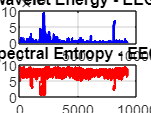

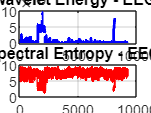

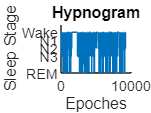

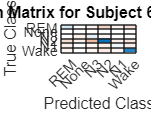


=== Processing patient 7 as test subject ===


Characteristics of EEG1 (Time-Domain):


Mean: 0.1629
Variance: 0.0198
Skewness: -0.0513
Kurtosis: 0.0056
Zero-Crossing Rate: 0.1305
Hjorth Activity: -0.1598
Hjorth Mobility: -0.1441
Hjorth Complexity: 0.0123


Characteristics of EEG2 (Time-Domain):


Mean: 0.0261
Variance: -0.2135
Skewness: -0.0569
Kurtosis: -0.0457
Zero-Crossing Rate: -0.0967
Hjorth Activity: 0.1239
Hjorth Mobility: 0.1421
Hjorth Complexity: -0.0234


Characteristics of EEG1 (Frequency-Domain):


Power Delta: 8342.0669
Power Theta: 3015.1777
Power Alpha: 16250.7399
Power Beta: 4874.3282
Power Gamma: 21155.5304
Spectral Edge Frequency: 6023.8947
Relative Delta: 9281.7551
Relative Theta: 4611.6760
Relative Alpha: 4697.1053
Relative Beta: 6782.4779
Relative Gamma: 5219.9735


Characteristics of EEG2 (Frequency-Domain):


Power Delta: 9327.1282
Power Theta: 2928.0047
Power Alpha: 8376.7920
Power Beta: 4231.3567
Power Gamma: 21630.7708
Spectral Edge Frequency: 3930.4638
Relative Delta: 6333.0173
Relative Theta: 3323.2778
Relative Alpha: 3551.0007
Relative Beta: 5196.6074
Relative Gamma: 2601.6914


Time-Frequency Features for EEG1 (Wavelet Energy & Spectral Entropy):


   1.0e+05 *

  Column 1

    1.2194
    0.6570
    0.7742
    0.5130
    0.7378
    0.5322
    0.7514
    0.6334
    0.4784
    0.5863
    0.5059
    0.5863
    1.0937
    0.5709
    0.8539
    0.8758
    0.8285
    1.0621
    0.8390
    1.0624
    1.1966
    0.6993
    0.8834
    1.2451
    0.3807
    0.4204
    0.7658
    0.0625
    0.0334
    0.0230
    0.0271
    0.4864
    0.1422
    0.0322
    0.0244
    0.0241
    0.0229
    0.0245
    0.0230
    0.0241
    0.0198
    0.0216
    0.0206
    0.0195
    0.0166
    0.0178
    0.0190
    0.0192
    0.0175
    0.0196
    0.1642
    0.2436
    0.0330
    0.0234
    0.0165
    0.0171
    0.0159
    0.0643
    0.0169
    0.0167
    0.0169
    0.1800
    0.1696
    0.0177
    0.0168
    0.0166
    0.0164
    0.0596
    0.1504
    0.0229
    0.0194
    0.0216
    0.0190
    0.0205
    0.0198
    0.0192
    0.0195
    0.0208
    0.0199
    0.0181
    0.0176
    0.0226
    0.0244
    0.0245
    0.0256
    0.0258
    0.1245
    0.0267
    0.

Time-Frequency Features for EEG2 (Wavelet Energy & Spectral Entropy):


   1.0e+05 *

  Column 1

    0.2596
    0.2090
    0.5629
    0.2498
    0.8051
    0.4453
    0.3881
    0.2599
    0.1625
    0.3329
    0.2445
    0.2558
    0.6691
    0.3502
    0.2544
    0.1435
    0.2567
    0.1931
    0.1816
    0.3349
    0.3141
    0.1517
    0.2973
    0.3530
    0.2268
    0.1165
    0.1037
    0.0388
    0.0212
    0.0169
    0.0184
    0.2002
    0.0404
    0.0196
    0.0170
    0.0169
    0.0175
    0.0167
    0.0154
    0.0160
    0.0136
    0.0145
    0.0152
    0.0143
    0.0118
    0.0133
    0.0114
    0.0123
    0.0116
    0.0134
    0.0445
    0.1195
    0.0364
    0.0198
    0.0153
    0.0140
    0.0140
    0.0354
    0.0171
    0.0150
    0.0141
    0.0430
    0.0593
    0.0121
    0.0116
    0.0120
    0.0109
    0.0351
    0.0865
    0.0189
    0.0171
    0.0151
    0.0168
    0.0185
    0.0151
    0.0168
    0.0155
    0.0164
    0.0146
    0.0164
    0.0154
    0.0170
    0.0174
    0.0173
    0.0170
    0.0166
    0.0882
    0.0185
    0.

Time-Frequency Features for EEG1 (Test Data):


   1.0e+05 *

  Column 1

    0.0827
    0.0164
    0.0260
    0.0161
    0.0352
    0.0155
    0.0397
    0.0437
    0.0139
    0.0368
    0.0285
    0.0420
    0.0209
    0.0551
    0.0245
    0.0251
    0.0396
    0.0506
    0.0273
    0.0500
    0.0172
    0.0415
    0.0192
    0.0250
    0.0812
    0.0340
    0.0434
    0.0546
    0.1091
    0.0220
    0.0733
    0.0232
    0.0146
    0.0314
    0.0357
    0.0618
    0.0431
    0.0137
    0.0728
    0.1951
    0.2047
    0.2001
    0.2399
    0.2271
    0.3426
    0.0996
    0.1307
    0.5398
    0.0809
    0.1245
    0.1431
    0.3445
    0.3805
    0.7679
    0.8614
    1.4764
    0.6787
    1.2577
    0.5746
    0.6899
    0.0302
    0.0143
    0.0148
    0.0620
    0.0375
    0.0203
    0.0127
    0.0799
    0.0378
    0.0393
    0.0445
    0.0359
    0.0835
    0.0151
    0.0330
    0.0426
    0.0561
    0.0287
    0.0173
    0.0392
    0.0207
    0.2247
    0.1077
    0.0134
    0.0292
    0.0130
    0.0135
    0.0259
    0.

Time-Frequency Features for EEG2 (Test Data):


   1.0e+05 *

  Column 1

    0.0308
    0.0121
    0.0164
    0.0123
    0.0230
    0.0120
    0.0113
    0.0188
    0.0101
    0.0113
    0.0191
    0.0199
    0.0123
    0.0140
    0.0139
    0.0134
    0.0301
    0.0346
    0.0131
    0.0195
    0.0127
    0.0153
    0.0133
    0.0146
    0.0789
    0.0133
    0.0161
    0.0392
    0.0939
    0.0124
    0.0720
    0.0160
    0.0184
    0.0371
    0.0397
    0.0279
    0.0190
    0.0373
    0.0814
    0.1676
    0.1563
    0.0837
    0.0732
    0.0770
    0.5563
    0.1085
    0.2627
    0.6986
    0.1143
    0.2132
    0.3174
    0.1466
    0.4271
    0.3841
    0.5414
    0.6939
    0.4775
    0.9542
    0.3814
    0.5734
    0.0243
    0.0105
    0.0109
    0.0214
    0.0296
    0.0109
    0.0112
    0.0571
    0.0563
    0.0244
    0.0184
    0.0128
    0.0717
    0.0149
    0.0153
    0.0235
    0.0125
    0.0101
    0.0100
    0.0227
    0.0125
    0.5685
    0.0795
    0.0087
    0.0284
    0.0193
    0.0319
    0.0398
    0.

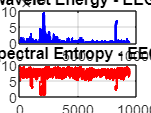

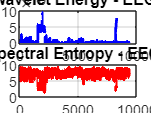

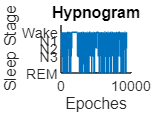

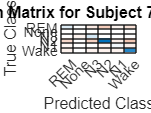


=== Processing patient 8 as test subject ===


Characteristics of EEG1 (Time-Domain):


Mean: 0.1629
Variance: 0.0198
Skewness: -0.0513
Kurtosis: 0.0056
Zero-Crossing Rate: 0.1305
Hjorth Activity: -0.1598
Hjorth Mobility: -0.1441
Hjorth Complexity: 0.0123


Characteristics of EEG2 (Time-Domain):


Mean: 0.0261
Variance: -0.2135
Skewness: -0.0569
Kurtosis: -0.0457
Zero-Crossing Rate: -0.0967
Hjorth Activity: 0.1239
Hjorth Mobility: 0.1421
Hjorth Complexity: -0.0234


Characteristics of EEG1 (Frequency-Domain):


Power Delta: 8342.0669
Power Theta: 3015.1777
Power Alpha: 16250.7399
Power Beta: 4874.3282
Power Gamma: 21155.5304
Spectral Edge Frequency: 6023.8947
Relative Delta: 9281.7551
Relative Theta: 4611.6760
Relative Alpha: 4697.1053
Relative Beta: 6782.4779
Relative Gamma: 5219.9735


Characteristics of EEG2 (Frequency-Domain):


Power Delta: 9327.1282
Power Theta: 2928.0047
Power Alpha: 8376.7920
Power Beta: 4231.3567
Power Gamma: 21630.7708
Spectral Edge Frequency: 3930.4638
Relative Delta: 6333.0173
Relative Theta: 3323.2778
Relative Alpha: 3551.0007
Relative Beta: 5196.6074
Relative Gamma: 2601.6914


Time-Frequency Features for EEG1 (Wavelet Energy & Spectral Entropy):


   1.0e+05 *

  Column 1

    1.2194
    0.6570
    0.7742
    0.5130
    0.7378
    0.5322
    0.7514
    0.6334
    0.4784
    0.5863
    0.5059
    0.5863
    1.0937
    0.5709
    0.8539
    0.8758
    0.8285
    1.0621
    0.8390
    1.0624
    1.1966
    0.6993
    0.8834
    1.2451
    0.3807
    0.4204
    0.7658
    0.0625
    0.0334
    0.0230
    0.0271
    0.4864
    0.1422
    0.0322
    0.0244
    0.0241
    0.0229
    0.0245
    0.0230
    0.0241
    0.0198
    0.0216
    0.0206
    0.0195
    0.0166
    0.0178
    0.0190
    0.0192
    0.0175
    0.0196
    0.1642
    0.2436
    0.0330
    0.0234
    0.0165
    0.0171
    0.0159
    0.0643
    0.0169
    0.0167
    0.0169
    0.1800
    0.1696
    0.0177
    0.0168
    0.0166
    0.0164
    0.0596
    0.1504
    0.0229
    0.0194
    0.0216
    0.0190
    0.0205
    0.0198
    0.0192
    0.0195
    0.0208
    0.0199
    0.0181
    0.0176
    0.0226
    0.0244
    0.0245
    0.0256
    0.0258
    0.1245
    0.0267
    0.

Time-Frequency Features for EEG2 (Wavelet Energy & Spectral Entropy):


   1.0e+05 *

  Column 1

    0.2596
    0.2090
    0.5629
    0.2498
    0.8051
    0.4453
    0.3881
    0.2599
    0.1625
    0.3329
    0.2445
    0.2558
    0.6691
    0.3502
    0.2544
    0.1435
    0.2567
    0.1931
    0.1816
    0.3349
    0.3141
    0.1517
    0.2973
    0.3530
    0.2268
    0.1165
    0.1037
    0.0388
    0.0212
    0.0169
    0.0184
    0.2002
    0.0404
    0.0196
    0.0170
    0.0169
    0.0175
    0.0167
    0.0154
    0.0160
    0.0136
    0.0145
    0.0152
    0.0143
    0.0118
    0.0133
    0.0114
    0.0123
    0.0116
    0.0134
    0.0445
    0.1195
    0.0364
    0.0198
    0.0153
    0.0140
    0.0140
    0.0354
    0.0171
    0.0150
    0.0141
    0.0430
    0.0593
    0.0121
    0.0116
    0.0120
    0.0109
    0.0351
    0.0865
    0.0189
    0.0171
    0.0151
    0.0168
    0.0185
    0.0151
    0.0168
    0.0155
    0.0164
    0.0146
    0.0164
    0.0154
    0.0170
    0.0174
    0.0173
    0.0170
    0.0166
    0.0882
    0.0185
    0.

Time-Frequency Features for EEG1 (Test Data):


   1.0e+04 *

  Column 1

    1.8279
    2.1640
    1.6711
    1.9966
    2.1394
    2.1417
    2.2708
    2.6985
    2.5493
    2.4841
    2.1035
    2.2711
    1.6578
    3.5279
    3.2140
    1.8525
    1.8135
    2.3855
    2.1241
    2.3521
    2.4645
    2.7520
    2.5545
    2.5652
    2.8502
    3.0433
    3.1197
    3.2295
    2.6975
    2.8682
    3.1444
    3.1583
    2.4829
    2.1248
    2.3809
    2.6221
    2.4070
    2.6953
    2.3293
    2.1658
    1.9820
    2.1058
    1.9882
    2.3289
    2.1746
    2.2873
    2.0239
    1.2290
    1.2710
    1.3909
    2.1382
    1.7639
    1.2573
    1.1600
    1.0684
    1.1358
    1.0454
    1.1317
    1.1073
    1.1138
    1.1691
    1.2214
    1.1711
    1.1631
    1.1987
    1.1437
    1.2226
    1.2711
    1.3094
    1.3580
    1.4750
    1.5898
    1.7355
    1.7782
    1.5860
    1.7131
    1.8519
    1.5204
    1.8338
    1.5726
    1.4751
    1.8567
    1.5461
    1.1594
    1.4276
    1.5532
    1.1685
    1.3168
    1.

Time-Frequency Features for EEG2 (Test Data):


   1.0e+04 *

  Column 1

    2.5276
    2.9505
    2.5868
    2.3561
    2.0467
    1.9914
    2.2487
    2.5147
    2.0668
    2.2269
    2.1887
    2.1803
    1.7455
    3.8755
    3.0220
    0.8085
    0.5320
    0.9553
    0.6993
    1.1064
    0.6712
    0.5555
    0.5772
    0.4416
    0.5950
    0.7399
    1.0319
    0.8469
    0.9800
    0.7647
    0.7197
    0.5168
    0.9598
    0.6852
    0.5380
    0.5390
    0.9128
    0.6822
    0.5388
    0.7950
    0.8028
    0.9919
    1.2171
    1.0064
    1.9412
    1.4445
    3.4002
    1.1227
    1.1079
    1.4347
    3.7797
    5.7851
    1.2947
    0.7687
    0.6019
    0.6180
    0.6218
    0.6235
    0.6676
    0.7309
    0.8102
    0.7150
    0.7275
    0.7373
    0.7404
    0.7950
    0.7920
    0.7085
    0.6764
    0.7981
    0.8071
    0.7712
    0.8439
    0.7537
    0.7295
    0.6007
    0.8048
    0.7212
    0.8091
    0.9602
    0.6606
    0.6815
    0.5482
    0.4919
    0.4408
    0.3574
    0.3202
    0.4024
    0.

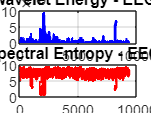

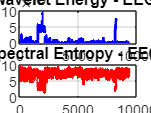

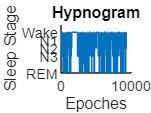

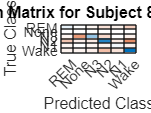


=== Processing patient 9 as test subject ===


Characteristics of EEG1 (Time-Domain):


Mean: 0.1629
Variance: 0.0198
Skewness: -0.0513
Kurtosis: 0.0056
Zero-Crossing Rate: 0.1305
Hjorth Activity: -0.1598
Hjorth Mobility: -0.1441
Hjorth Complexity: 0.0123


Characteristics of EEG2 (Time-Domain):


Mean: 0.0261
Variance: -0.2135
Skewness: -0.0569
Kurtosis: -0.0457
Zero-Crossing Rate: -0.0967
Hjorth Activity: 0.1239
Hjorth Mobility: 0.1421
Hjorth Complexity: -0.0234


Characteristics of EEG1 (Frequency-Domain):


Power Delta: 8342.0669
Power Theta: 3015.1777
Power Alpha: 16250.7399
Power Beta: 4874.3282
Power Gamma: 21155.5304
Spectral Edge Frequency: 6023.8947
Relative Delta: 9281.7551
Relative Theta: 4611.6760
Relative Alpha: 4697.1053
Relative Beta: 6782.4779
Relative Gamma: 5219.9735


Characteristics of EEG2 (Frequency-Domain):


Power Delta: 9327.1282
Power Theta: 2928.0047
Power Alpha: 8376.7920
Power Beta: 4231.3567
Power Gamma: 21630.7708
Spectral Edge Frequency: 3930.4638
Relative Delta: 6333.0173
Relative Theta: 3323.2778
Relative Alpha: 3551.0007
Relative Beta: 5196.6074
Relative Gamma: 2601.6914


Time-Frequency Features for EEG1 (Wavelet Energy & Spectral Entropy):


   1.0e+05 *

  Column 1

    1.2194
    0.6570
    0.7742
    0.5130
    0.7378
    0.5322
    0.7514
    0.6334
    0.4784
    0.5863
    0.5059
    0.5863
    1.0937
    0.5709
    0.8539
    0.8758
    0.8285
    1.0621
    0.8390
    1.0624
    1.1966
    0.6993
    0.8834
    1.2451
    0.3807
    0.4204
    0.7658
    0.0625
    0.0334
    0.0230
    0.0271
    0.4864
    0.1422
    0.0322
    0.0244
    0.0241
    0.0229
    0.0245
    0.0230
    0.0241
    0.0198
    0.0216
    0.0206
    0.0195
    0.0166
    0.0178
    0.0190
    0.0192
    0.0175
    0.0196
    0.1642
    0.2436
    0.0330
    0.0234
    0.0165
    0.0171
    0.0159
    0.0643
    0.0169
    0.0167
    0.0169
    0.1800
    0.1696
    0.0177
    0.0168
    0.0166
    0.0164
    0.0596
    0.1504
    0.0229
    0.0194
    0.0216
    0.0190
    0.0205
    0.0198
    0.0192
    0.0195
    0.0208
    0.0199
    0.0181
    0.0176
    0.0226
    0.0244
    0.0245
    0.0256
    0.0258
    0.1245
    0.0267
    0.

Time-Frequency Features for EEG2 (Wavelet Energy & Spectral Entropy):


   1.0e+05 *

  Column 1

    0.2596
    0.2090
    0.5629
    0.2498
    0.8051
    0.4453
    0.3881
    0.2599
    0.1625
    0.3329
    0.2445
    0.2558
    0.6691
    0.3502
    0.2544
    0.1435
    0.2567
    0.1931
    0.1816
    0.3349
    0.3141
    0.1517
    0.2973
    0.3530
    0.2268
    0.1165
    0.1037
    0.0388
    0.0212
    0.0169
    0.0184
    0.2002
    0.0404
    0.0196
    0.0170
    0.0169
    0.0175
    0.0167
    0.0154
    0.0160
    0.0136
    0.0145
    0.0152
    0.0143
    0.0118
    0.0133
    0.0114
    0.0123
    0.0116
    0.0134
    0.0445
    0.1195
    0.0364
    0.0198
    0.0153
    0.0140
    0.0140
    0.0354
    0.0171
    0.0150
    0.0141
    0.0430
    0.0593
    0.0121
    0.0116
    0.0120
    0.0109
    0.0351
    0.0865
    0.0189
    0.0171
    0.0151
    0.0168
    0.0185
    0.0151
    0.0168
    0.0155
    0.0164
    0.0146
    0.0164
    0.0154
    0.0170
    0.0174
    0.0173
    0.0170
    0.0166
    0.0882
    0.0185
    0.

Time-Frequency Features for EEG1 (Test Data):


   1.0e+05 *

  Column 1

    0.0814
    0.0838
    0.1336
    0.1809
    0.3533
    0.1691
    0.0782
    0.0771
    0.0999
    0.0811
    0.0822
    0.2271
    0.0839
    0.0863
    0.0969
    0.0911
    0.1143
    0.0872
    0.0824
    0.1193
    0.1371
    0.1218
    0.1208
    0.1094
    0.1125
    0.0900
    0.1003
    0.1003
    0.1150
    0.0997
    0.1299
    0.1180
    0.1478
    0.1946
    0.1756
    0.1588
    0.1235
    0.1327
    0.1512
    0.1469
    0.2123
    0.1263
    0.1122
    0.2010
    0.1113
    0.1048
    0.0999
    0.1110
    0.1235
    0.1636
    0.1497
    0.2646
    0.1882
    0.1905
    0.2119
    0.2084
    0.1903
    0.2035
    0.1885
    0.1431
    0.1576
    0.1385
    0.1529
    0.1650
    0.1643
    0.2522
    0.2480
    0.3573
    0.1657
    0.3657
    0.2183
    0.2673
    0.2052
    0.2694
    0.0704
    0.1265
    0.1078
    0.1202
    0.2152
    0.2191
    0.2038
    0.1918
    0.1906
    0.2775
    0.2324
    0.1993
    0.1909
    0.2210
    0.

Time-Frequency Features for EEG2 (Test Data):


   1.0e+05 *

  Column 1

    0.0312
    0.0592
    0.1264
    0.1476
    0.3526
    0.1771
    0.0621
    0.0594
    0.0827
    0.0829
    0.0610
    0.2564
    0.0747
    0.0537
    0.0764
    0.0858
    0.0882
    0.0647
    0.0655
    0.0809
    0.0836
    0.0895
    0.0747
    0.0490
    0.0611
    0.0523
    0.0545
    0.0605
    0.0644
    0.0574
    0.0831
    0.0595
    0.0654
    0.1163
    0.1001
    0.0944
    0.0795
    0.0914
    0.1066
    0.1018
    0.0945
    0.0762
    0.0859
    0.1270
    0.0752
    0.0777
    0.0895
    0.0794
    0.0853
    0.0822
    0.0744
    0.1578
    0.1161
    0.1102
    0.1305
    0.1182
    0.0944
    0.0959
    0.1347
    0.1473
    0.0930
    0.1437
    0.1466
    0.1645
    0.0978
    0.1666
    0.2010
    0.2872
    0.1303
    0.2623
    0.1487
    0.2219
    0.1583
    0.2486
    0.0351
    0.1437
    0.0913
    0.0624
    0.1507
    0.1399
    0.1255
    0.0984
    0.1438
    0.2233
    0.1547
    0.1166
    0.1034
    0.1228
    0.

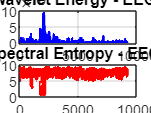

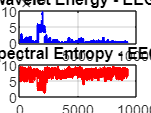

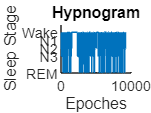

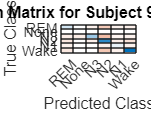


=== Processing patient 10 as test subject ===


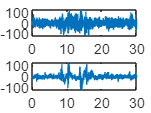

Characteristics of EEG1 (Time-Domain):


Mean: 0.1629
Variance: 0.0198
Skewness: -0.0513
Kurtosis: 0.0056
Zero-Crossing Rate: 0.1305
Hjorth Activity: -0.1598
Hjorth Mobility: -0.1441
Hjorth Complexity: 0.0123


Characteristics of EEG2 (Time-Domain):


Mean: 0.0261
Variance: -0.2135
Skewness: -0.0569
Kurtosis: -0.0457
Zero-Crossing Rate: -0.0967
Hjorth Activity: 0.1239
Hjorth Mobility: 0.1421
Hjorth Complexity: -0.0234


Characteristics of EEG1 (Frequency-Domain):


Power Delta: 8342.0669
Power Theta: 3015.1777
Power Alpha: 16250.7399
Power Beta: 4874.3282
Power Gamma: 21155.5304
Spectral Edge Frequency: 6023.8947
Relative Delta: 9281.7551
Relative Theta: 4611.6760
Relative Alpha: 4697.1053
Relative Beta: 6782.4779
Relative Gamma: 5219.9735


Characteristics of EEG2 (Frequency-Domain):


Power Delta: 9327.1282
Power Theta: 2928.0047
Power Alpha: 8376.7920
Power Beta: 4231.3567
Power Gamma: 21630.7708
Spectral Edge Frequency: 3930.4638
Relative Delta: 6333.0173
Relative Theta: 3323.2778
Relative Alpha: 3551.0007
Relative Beta: 5196.6074
Relative Gamma: 2601.6914


Time-Frequency Features for EEG1 (Wavelet Energy & Spectral Entropy):


   1.0e+05 *

  Column 1

    1.2194
    0.6570
    0.7742
    0.5130
    0.7378
    0.5322
    0.7514
    0.6334
    0.4784
    0.5863
    0.5059
    0.5863
    1.0937
    0.5709
    0.8539
    0.8758
    0.8285
    1.0621
    0.8390
    1.0624
    1.1966
    0.6993
    0.8834
    1.2451
    0.3807
    0.4204
    0.7658
    0.0625
    0.0334
    0.0230
    0.0271
    0.4864
    0.1422
    0.0322
    0.0244
    0.0241
    0.0229
    0.0245
    0.0230
    0.0241
    0.0198
    0.0216
    0.0206
    0.0195
    0.0166
    0.0178
    0.0190
    0.0192
    0.0175
    0.0196
    0.1642
    0.2436
    0.0330
    0.0234
    0.0165
    0.0171
    0.0159
    0.0643
    0.0169
    0.0167
    0.0169
    0.1800
    0.1696
    0.0177
    0.0168
    0.0166
    0.0164
    0.0596
    0.1504
    0.0229
    0.0194
    0.0216
    0.0190
    0.0205
    0.0198
    0.0192
    0.0195
    0.0208
    0.0199
    0.0181
    0.0176
    0.0226
    0.0244
    0.0245
    0.0256
    0.0258
    0.1245
    0.0267
    0.

Time-Frequency Features for EEG2 (Wavelet Energy & Spectral Entropy):


   1.0e+05 *

  Column 1

    0.2596
    0.2090
    0.5629
    0.2498
    0.8051
    0.4453
    0.3881
    0.2599
    0.1625
    0.3329
    0.2445
    0.2558
    0.6691
    0.3502
    0.2544
    0.1435
    0.2567
    0.1931
    0.1816
    0.3349
    0.3141
    0.1517
    0.2973
    0.3530
    0.2268
    0.1165
    0.1037
    0.0388
    0.0212
    0.0169
    0.0184
    0.2002
    0.0404
    0.0196
    0.0170
    0.0169
    0.0175
    0.0167
    0.0154
    0.0160
    0.0136
    0.0145
    0.0152
    0.0143
    0.0118
    0.0133
    0.0114
    0.0123
    0.0116
    0.0134
    0.0445
    0.1195
    0.0364
    0.0198
    0.0153
    0.0140
    0.0140
    0.0354
    0.0171
    0.0150
    0.0141
    0.0430
    0.0593
    0.0121
    0.0116
    0.0120
    0.0109
    0.0351
    0.0865
    0.0189
    0.0171
    0.0151
    0.0168
    0.0185
    0.0151
    0.0168
    0.0155
    0.0164
    0.0146
    0.0164
    0.0154
    0.0170
    0.0174
    0.0173
    0.0170
    0.0166
    0.0882
    0.0185
    0.

Time-Frequency Features for EEG1 (Test Data):


   1.0e+05 *

  Column 1

    0.0803
    0.1777
    0.0784
    0.0790
    0.2109
    0.1805
    0.1021
    0.1363
    0.0712
    0.0910
    0.2304
    0.0770
    0.1045
    0.1982
    0.1033
    0.0822
    0.2558
    0.1382
    0.0934
    0.2563
    0.0896
    0.0896
    0.2543
    0.3054
    0.1547
    0.0864
    0.1113
    0.2137
    0.2920
    0.0986
    0.0746
    0.0829
    0.0685
    0.0805
    0.1084
    0.0754
    0.0626
    0.0859
    0.0651
    0.0789
    0.1193
    0.0699
    0.4990
    0.0823
    0.0756
    0.0737
    0.0733
    0.0751
    0.0848
    0.0713
    0.0944
    0.1215
    0.0953
    0.1063
    0.0811
    0.1447
    0.2078
    0.1413
    0.1227
    0.1238
    0.0933
    0.1025
    0.0592
    0.0952
    0.1708
    0.2102
    0.2390
    0.2128
    0.3164
    0.2233
    0.5495
    0.3528
    0.0754
    0.0671
    0.0848
    0.0552
    0.0557
    0.0691
    0.0663
    0.4926
    0.2879
    0.2077
    0.0931
    0.4524
    0.2146
    0.0898
    0.8546
    0.0929
    0.

Time-Frequency Features for EEG2 (Test Data):


   1.0e+04 *

  Column 1

    0.3285
    1.8604
    0.4232
    0.3512
    1.2611
    0.6728
    0.6536
    1.1225
    0.3322
    0.5369
    1.3426
    0.4588
    0.4982
    1.1107
    0.5734
    0.4455
    0.8625
    0.7905
    0.5842
    2.3021
    0.6575
    0.4895
    1.8006
    2.2531
    0.5968
    0.4031
    0.4826
    1.3125
    2.4184
    0.6026
    0.3264
    0.3823
    0.3293
    0.5989
    0.5651
    0.3768
    0.3123
    0.5770
    0.3780
    0.4471
    0.6466
    0.5485
    3.2698
    0.3966
    0.4513
    0.4546
    0.4858
    0.4848
    0.6530
    0.4762
    0.6272
    0.8326
    0.7751
    0.6482
    0.3809
    1.0551
    2.7826
    1.2675
    0.6542
    0.7081
    0.5894
    0.9676
    0.2539
    0.5294
    1.3428
    0.7735
    1.4490
    1.2160
    2.3952
    1.6376
    2.0616
    3.4027
    0.3677
    0.4379
    0.5096
    0.2497
    0.3584
    0.3642
    0.4356
    1.1133
    1.7144
    2.0057
    0.5361
    1.7560
    1.1063
    0.6234
    4.0225
    0.5864
    0.

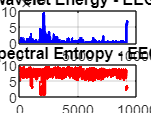

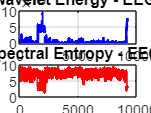

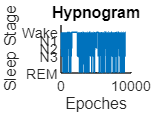

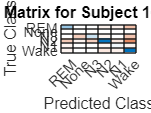

features = [features_time_eeg1, features_freq_eeg1];
features = normalize(features);
labels = categorical(STAGE, [0 1 2 3 4 5], {'REM', 'None', 'N3', 'N2', 'N1', 'Wake'});
    
features_test = [features_time_eeg1_test, features_freq_eeg1_test];
features_test = normalize(features_test);
labels_test = categorical(STAGE_test, [0 1 2 3 4 5], {'REM', 'None', 'N3', 'N2', 'N1', 'Wake'});

figure;
plot(STAGE); %sleep stages are for 30 seconds epochs
ylim([0 6]);
set(gca,'ytick',0:6,'yticklabel',{'REM','','N3','N2','N1','Wake',''});
xlabel('Epoches');
ylabel('Sleep Stage');
box off;
title('Hypnogram');
set(gcf,'color','w');

% Train and test
[trainedClassifier, validationAccuracy, f1Score, perStageAccuracy] = trainClassifier3(features, labels);
    
% Store test results
testPredictions = predict(trainedClassifier.ClassificationKNN, features_test);
all_test_predictions{test} = testPredictions;
all_test_labels{test} = labels_test;
all_test_indices = [all_test_indices; test*ones(length(labels_test),1)];
    
% Calculate and store accuracy for this test subject
correct_predictions = sum(testPredictions == labels_test);
total_predictions = length(labels_test);
subject_accuracy = correct_predictions / total_predictions;
overall_accuracies(test) = mean(subject_accuracy);
overall_accuracies(test) = subject_accuracy(1); 
    
% Store per-subject results
per_subject_results{test} = struct(...
    'predictions', testPredictions, ...
    'labels', labels_test, ...
    'accuracy', subject_accuracy, ...
    'confusion', confusionmat(labels_test, testPredictions));
    
% Plot confusion matrix for this subject
figure;
confusionchart(labels_test, testPredictions);
title(sprintf('Confusion Matrix for Subject %d (Held-Out Test)', test));
end


%% Display overall results
fprintf('\n=== Leave-One-Out Cross-Validation Results ===\n');


=== Leave-One-Out Cross-Validation Results ===


fprintf('Individual Subject Accuracies:\n');

Individual Subject Accuracies:


for i = 1:10
    fprintf('Subject %d: %.2f%%\n', i, overall_accuracies(i)*100);
end

Subject 1: 32.41%
Subject 2: 48.89%
Subject 3: 31.20%
Subject 4: 47.94%
Subject 5: 31.49%
Subject 6: 33.89%
Subject 7: 37.47%
Subject 8: 37.06%
Subject 9: 29.95%
Subject 10: 46.72%


fprintf('\nMean Accuracy: %.2f%%\n', mean(overall_accuracies)*100);


Mean Accuracy: 37.70%


fprintf('Standard Deviation: %.2f%%\n', std(overall_accuracies)*100);

Standard Deviation: 7.42%


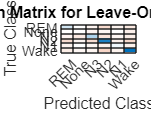

% Combine all predictions and labels for overall confusion matrix
categories = {'REM', 'None', 'N3', 'N2', 'N1', 'Wake'};
all_predictions_combined = [];
all_labels_combined = [];

for i = 1:10
    % Convert to categorical if not already
    if ~iscategorical(all_test_predictions{i})
        current_pred = categorical(all_test_predictions{i}, 0:5, categories);
    else
        current_pred = all_test_predictions{i};
    end
    
    if ~iscategorical(all_test_labels{i})
        current_labels = categorical(all_test_labels{i}, 0:5, categories);
    else
        current_labels = all_test_labels{i};
    end
    
    % Ensure consistent categories
    current_pred = reordercats(current_pred, categories);
    current_labels = reordercats(current_labels, categories);
    
    all_predictions_combined = [all_predictions_combined; current_pred(:)];
    all_labels_combined = [all_labels_combined; current_labels(:)];
end

% Plot overall confusion matrix
figure;
confusionchart(all_labels_combined, all_predictions_combined);
title('Overall Confusion Matrix for Leave-One-Out Cross-Validation');